%{
n = 17;
rng(n, "philox");
M = randi([100000 1000000]) / 1000 / sqrt(2)
m = randi([1000 10000]) / 1000 * sqrt(3)
l = randi([100 1000]) / sqrt(5) / 100
%}

M = 264.5866;
m = 9.1747;
l = 2.5849;
g = 9.81;

A = [0, 1, 0, 0;
    0, 0, (3*g*m)/(m+4*M), 0;
    0, 0, 0, 1;
    0, 0, (6*g*(m+M))/(l*(m+4*M)), 0]

A =          0    1.0000         0         0
         0         0    0.2529         0
         0         0         0    1.0000
         0         0    5.8395         0



B = [0; 4/(m+4*M); 0; 6/(l*(m+4*M))];
C = [1, 0, 0, 0; 0, 0, 1, 0];
D = [0; 6/(l*(m+4*M)); 0; (12*(m+M))/(l^2*m*(m+4*M))];


%[V_A eig_A] = eig(A);

U_A = [B A*B A^2*B A^3*B];
ru = rank(U_A);
V_A = [C; C*A; C*A^2; C*A^3];
rv = rank(V_A);

sys_uy = ss(A, B, C, 0); % Создание системы (D=0 для W_uy)
sys_fy = ss(A, D, C, 0);  % Создание системы (B=0 для W_fy)

% Передаточные функции
W_uy = tf(sys_uy);
W_fy = tf(sys_fy);
zero(W_uy(1));
zero(W_uy(2));
zero(W_fy(1));
zero(W_fy(2));

pole(W_uy(1));
pole(W_uy(2));
pole(W_fy(1));
pole(W_fy(2));



Gamma_r = [-1 0 0 0; 0 -2 0 0; 0 0 -3 -3; 0 0 3 -3];
Y_r = [1 1 1 1];

cvx_begin sdp

variable P_r(4, 4)
A*P_r-P_r*Gamma_r == B*Y_r;

cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


A*P_r;
P_r;
det(P_r);
K = -Y_r*pinv(P_r)

K = 1.0e+04 *

    0.1688    0.3094   -2.3070   -0.9471



eig(A+B*K)

ans =   -3.0000 + 3.0000i
  -3.0000 - 3.0000i
  -2.0000 + 0.0000i
  -1.0000 + 0.0000i




x_00 = [100; 0; 0.0; 0.0]

x_00 =    100
     0
     0
     0


x_02 = [0.01; 0.01; 0.05; 0.01];
x_03 = [0.01; 0.05; 0.01;0.01];
x_04 = [0.01; 0.01; 0.01; 0.05]; % это x1
x_044 = [0.01; 0.01; pi/4; 0.01];
x_05 = [0.01; 0.01; 0.01; 1];
x_06 = [0.01; 25; 0.01; 0.01];
x_07 = [0.01; 0.01; 0.01; 0.01];
x_0 = x_07;
%u = 0;    % Управляющая сила (Н)
f = 0;


%{
open_system('task_1_lin');
set_param('task_1_lin/x_l', 'VariableName', 'x_l')
set_param('task_1_lin/y', 'VariableName', 'y')
out = sim('task_1_lin');

figure('Position', [100 100 800 400])

subplot(2,2,1);
plot(out.x_l.Time, out.x_l.Data(1,:),'b-', 'LineWidth',2);
legend('$x_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northwest')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,2);
plot(out.x_l.Time, out.x_l.Data(2,:),'c-', 'LineWidth',2);
legend('$x_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northwest')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,3);
plot(out.x_l.Time, out.x_l.Data(3,:),'m-', 'LineWidth',2);
legend('$x_3(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northwest')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,4);
plot(out.x_l.Time, out.x_l.Data(4,:),'g-', 'LineWidth',2);
legend('$x_4(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northwest')
ylabel('f(t)')
xlabel('t, s')
grid()


sgtitle('Graph $x(t)$ for $x(0) = [0.01, 0.01, 0.05, 0.01]^T$, linear','Interpreter','latex',  'FontSize', 14)

full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\3_x_lin_02_sm.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);
%}


% Временной интервал
tspan = [0 6];
  

% Решение ОДУ
[t, x] = ode45(@(t,x) pendulum_ode(t,x,K,f,m,M,l,g), tspan, x_0);

u = zeros(length(t), 1);
for i = 1:length(t)
    [~, u_i] = pendulum_ode(t(i), x(i, :)', K, f, m, M, l, g);
    u(i) = u_i;
end

%plot(t, u);
max_phi = max(x(:,3))

max_phi = 0.0101

min(x(:,3))

ans = -0.0061

max_a = max(x(:,1))

max_a = 0.0100

min(x(:,1))

ans = -0.0329

max_u = max(u)

max_u = 62.8374

min(u)

ans = -277.5976

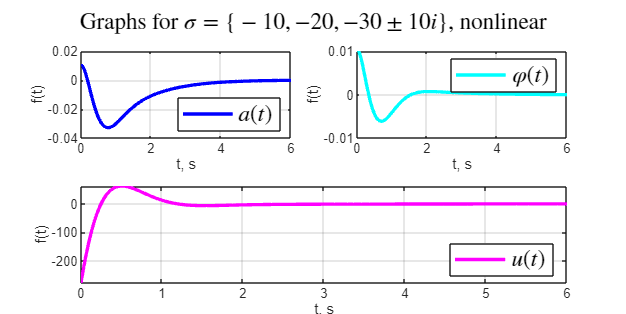



% Графики
figure('Position', [100 100 800 400])
subplot(2,2,1);
plot(t, x(:,1), 'b-', 'LineWidth',2); 
legend('$a(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,2);
plot(t, x(:,3), 'c-', 'LineWidth',2); 
legend('$\varphi (t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,[3 4]);
plot(t,  u, 'm-', 'LineWidth',2);
legend('$u(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
grid()


sgtitle('Graphs for $\sigma =\{-10, -20, -30 \pm 10i \}$, nonlinear','Interpreter','latex',  'FontSize', 14)
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\3_x_nlin_s4.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);






%{
% Графики
figure('Position', [100 100 800 400])
subplot(2,2,1);
plot(t, x(:,1), 'b-', 'LineWidth',2); 
legend('$x_1(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,2);
plot(t, x(:,2), 'c-', 'LineWidth',2); 
legend('$x_2(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,3);
plot(t, x(:,3), 'm-', 'LineWidth',2);
legend('$x_3(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
grid()

subplot(2,2,4);
plot(t, x(:,4), 'g-', 'LineWidth',2); 
legend('$x_4(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'northeast')
ylabel('f(t)')
xlabel('t, s')
grid()

sgtitle('Graph $x(t)$ for $x(0) = [1000, 0.01, 0.01, 0.01]^T$, nonlinear','Interpreter','latex',  'FontSize', 14)
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic\3_x_nlin_08_lg.png'];

%exportgraphics(gcf, full_path, 'Resolution', 300);
%}
